# q1

dt = 10000;
t = -1:1/dt:1;
a = 1 + mod(494, 3);
subplot(2,2,1);
%nexttile
y1= sin(20*pi*t*a);
plot(t,y1);
xlabel("Time (sec)");
ylabel("Amplitude") ;
title("y1(t)");

subplot(2,2,2);
%nexttile
y2= cos(5*pi*t*a + pi/4);
plot(t,y2);
xlabel("Time (sec)");
ylabel("Amplitude") ;
title("y2(t)");

subplot(2,2,3);
%nexttile
y3= exp(-2*a*t);
plot(t,y3);
xlabel("Time (sec)");
ylabel("Amplitude") ;
title("y3(t)");

subplot(2,2,4);
%nexttile
y4= (exp(-0.25*a*t)).*sin(20*pi*t);
plot(t,y4);
xlabel("Time (sec)");
ylabel("Amplitude") ;
title("y4(t)");
subplot(2,2,4);

## q2

dt = 10000;
t = -5:1/dt:5;
a = 1 + mod(494, 3);
%x1=inline('exp(-a.*t)','t');
x1=exp(-a*t);

subplot(2,2,1);
plot(t,x1);
xlabel("Time (sec)");
ylabel("Amplitude") ;
title("x1(t)");

subplot(2,2,2);
plot(-t,x1);
xlabel("Time (sec)");
ylabel("Amplitude") ;
title("x2(t)");

subplot(2,2,3);
plot(t-1.5*a,x1);
xlabel("Time (sec)");
ylabel("Amplitude") ;
title("x3(t)");

subplot(2,2,4);
plot(2*a*t,x1);
xlabel("Time (sec)");
ylabel("Amplitude") ;
title("x4(t)");

## q3-a

data = load('ECG_Data.txt');
plot(data);
xlabel('Sample');
ylabel('ECG Value');
title("ECG data plot");
grid on;

## q3-b

datajan=load('RainFallIndia_Jan.txt');
datajuly=load('RainFallIndia_July.txt');
histogram(datajan);
histogram(datajuly);
meanjan=mean(datajan);
stddjan=std(datajan);
meanjuly=mean(datajuly);
stddjuly=std(datajuly);

## q3-c

file='Track001.wav';
Fs=1/100000;
[y,Fs]=audioread(file);
sound(y,Fs);

## q4

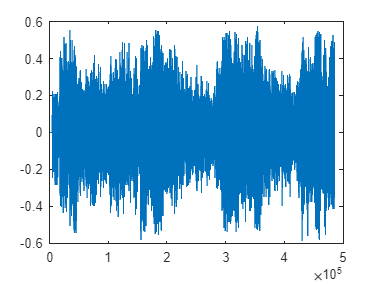

[y,Fs] = audioread("Track001.wav");
%sound(y,Fs)
F = 250*a;
Y = y *cos(2*pi*F/Fs);
%sound(y,Fs)
figure; plot(y) 

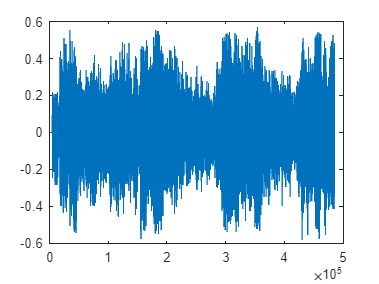

figure; plot(Y)

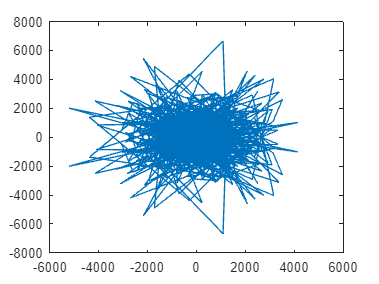

Fy = fft(y);
FY = fft(Y);
figure; plot(Fy) 

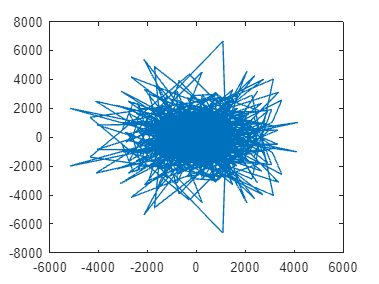

figure; plot(FY)

## q5

T = 5000*0.001;
a = 1 + mod(494, 3);
t = linspace(0,T,5000);
w1 = sin(200*a*t);
w2 = sin(220*a*t);
Fs = 44100;
w3 = [w1(1:2500) w2(2501:5000)];
audiowrite("sg1.wav",w3,Fs);
sound(w3,Fs)

## q6

t = linspace(0,5,10000)
f1 = sin(2*pi*436*t); %LA
f2 = sin(2*pi*490.94*t); %SI
f3 = sin(2*pi*261.63*t); %DO
f4 = sin(2*pi*293.66 *t); %RA
f5 = sin(2*pi*329.63 *t); %ME
f6 = sin(2*pi*349.23*t); %FA
f7 = sin(2*pi*392.00 *t); %SOL
f9= sin(2*pi*523.00 *t); %si
f8 = [f3 f4 f5 f6 f7 f1 f2 f9];
Fs = 5000;
%Fs alias sampling frewuency should be about twice the given frequecny
audiowrite("sg2.wav",f8,Fs);
sound(f8,Fs)

## q7

a;
Fs = 4100;
load('ConvFile2.txt');
h = ConvFile2;
[s,Fs] = audioread("Track002.wav");
sound(s,Fs);
x= conv2(s,h);
audiowrite("sg3.wav",x,Fs);
sound(x,Fs);